# PTC Design (PTCEL17R121NBE)

How to select?

- Find R25 (ptc resistance at 25 degree) value based on maximum inrush current.

- Calculate power desipation accross the resistos based on the E(t) shown in the equation.

- Check the interal stored energy from PTC J/K. 

- Check the stored energy is greater than the heat desipation while precharge.

- check for mutiple cycles i.e turn on off the machine

                       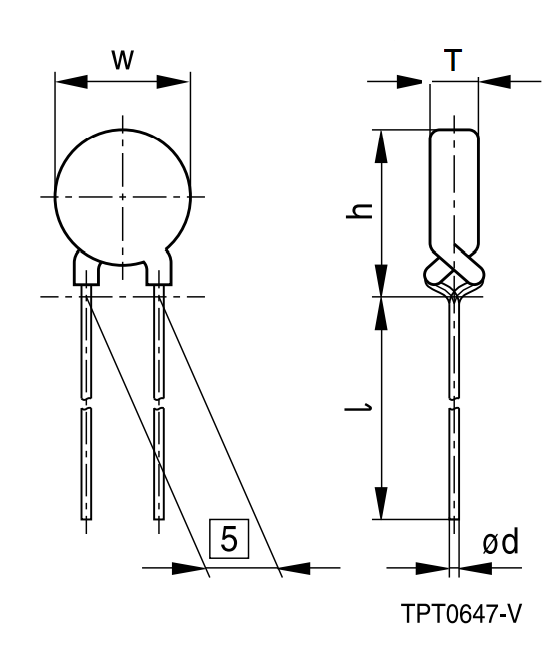        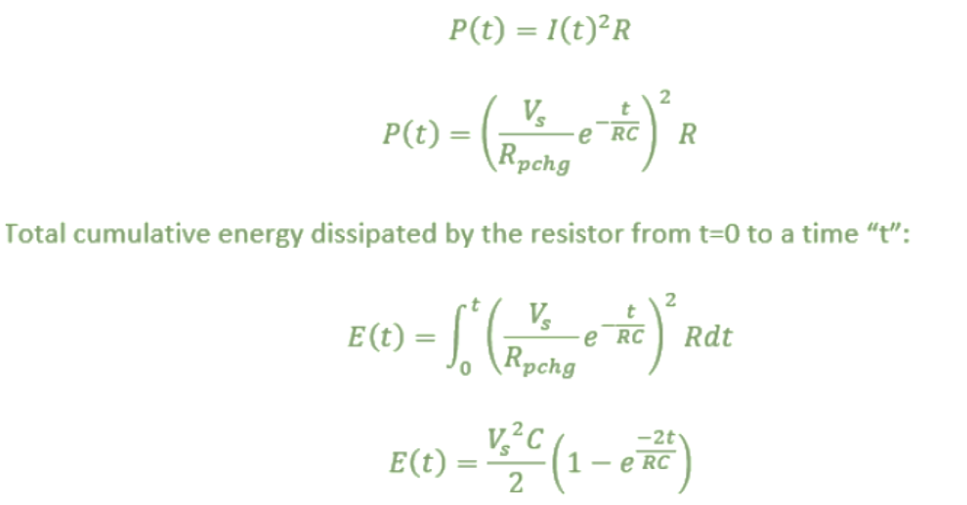

R25 = 120; %ohms
CTH = 2.3; % J/K Jules required to raise 1 degree in PTC
C_DC_LINK = 1700; % uF DC link capacitor
V_AC_PEAK = 325; % DC LINK VOLTAGE
DIA_PTC = 16.5; % mm PTC DIA // not used as Cth (J/K) is given
THICK_PTC = 7.5; % mm  PTC thickness // not used as Cth (J/K) is given


Environment conditions:

AMBIENT = 60; % in degree 
CRITICAL_TEMP = 100; % degree Critical temperature at which PTC resistance start increase
DELTA_T = CRITICAL_TEMP - AMBIENT;

Calculate Energy Desipated in Resistor:

E_PTC = CTH * DELTA_T

E_PTC = 92

E_DES = 1/2 * C_DC_LINK * 1e-6* V_AC_PEAK ^ 2 % Jule

E_DES = 89.7812

Time constant to charge the DC link Cap (5* R * C):

T = 5 * R25 * C_DC_LINK * 1e-6

T = 1.0200